# LQR 

Vamos ver ejemplos de ajuste de la constante K empleando LQR

Tomamos como punto de partida nuestro sistema controlable de otras veces


$$$A_c =\pmatrix{1&2&0 \cr
-2&3&0\cr
1&0&-2}, \ B = \pmatrix{1& 2\cr
1&0\cr
0&0}$$


Ac = [1 2 0; -2 3 0; 1 0 -2];
B = [1 2;1 0;0 0]; 

El ajuste de las constantes depende de qué es lo que queremos minimizar supongamos por ejemplo que no queremos que ninguno de los estados alcance un valor  mayor  que tres, y que este es nuestro único criterio,

Entonces, podemos centrar nuestro diseñoi en $\bar{Q}$, empleamos el criterio de Bryson y hacemos que todos los valores de la diagonal de $\bar{Q}$ sean de la forma $\frac{1}{3^2}$. Como no tengo criterios para $\bar{R}$ la tomo directamente como la matriz identidad deberá tener dimension (2x2) puesto que el vector de entradas es (2x2). Además puedo tomar, por ejemplo, $\rho =0.01$ de este modo, LQR  da más peso a la condición de los estados, puesto que las entradas no tengo restricción alguna.

Hay que tener en cuenta, que los valores que introducimos son siempre relativos, en general, cuanto mayor el valor de $\bar{Q_{ii}$ más obligamos a que la variable correspondiente sea pequeña, lo mismo para $\bar{R_{ii}$

Qbar =[1/3^2 0 0; 0 1/3^2 0; 0 0 1/3^2]; %criterio de Bryson
Rbar = eye(2);
rho = 0.001;

Ahora debemos construir las matrices $Q,R,N$. Pero ¿Cúal es la salida z que para la que yo quiero optimizar? En realidad son directamente los estados $z = Ix+0u$

Luego $G=I$y $H$ deberá ser una matriz de ceros que tenga las mismas dimensiones que $B$ (Tengo que ajustar entradas con estados)


G = eye(3)

G =      1     0     0
     0     1     0
     0     0     1


H =zeros(3,2)

H =      0     0
     0     0
     0     0


Ahora solo tengo que construir mis matrices para resolver la ecuación de Ricatti

$Q = G^T\bar{Q}G$, $R=H^T\bar{Q}H+\rho \bar{R}$, $N = G^T\bar{Q}H$

Q = G'*Qbar*G

Q =     0.1111         0         0
         0    0.1111         0
         0         0    0.1111


R = H'*Qbar*H+rho*Rbar

R = 	1.0e+-3 *

    1.0000         0
         0    1.0000


N = G'*Qbar*H %aquí va a ser cero pero hace falta para lqr

N =      0     0
     0     0
     0     0


Resolvemos la ecuación de Riccati empleando el comando lqr de matlab,

[K,P,la]= lqr(Ac,B,Q,R,N) 

K =     2.7573   12.5952    1.0762
   11.3338   -5.8192    1.9747


P =     0.0057   -0.0029    0.0010
   -0.0029    0.0155    0.0001
    0.0010    0.0001    0.0265


la =    -2.2264
   -9.9433
  -23.8504


K=ganancia de la realimentación, P solución de la ecuación de Riccati asociada al problema, la autovalores del sistema en lazo cerrado (A-BK), recordad que (A-BK) debe ser una matriz de estabilidad (Kurwitz)

Si nos fijamos en los autovalores, resulta que el sistema en lazo cerrado es estable, Vamos a simularlo a ver que salidas da

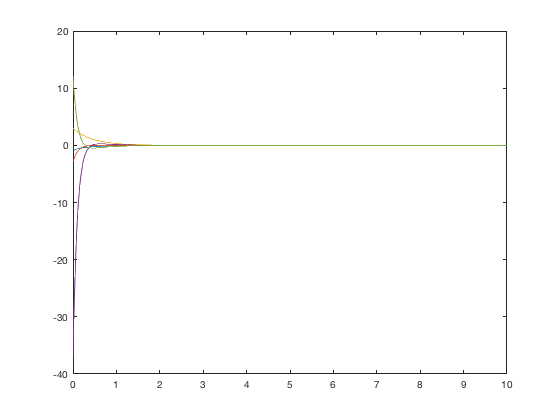

sys = @(t,x)sistema_lineal(t,x,K,Ac,B);
tf = 10;
x0 = [-1;-3;3];
%opciones = odeset('maxstep',1e-5);
[t,x] = ode45(sys,[0,tf],x0); %opciones);
figure(1)
plot(t,x)
hold on
% lambda = [-1,-2,-3];
% K2 = place(Ac,B,lambda)
% sys = @(t,x)sistema_lineal(t,x,K2,Ac,B);
% [t,x] = ode45(sys,[0,tf],x0); %opciones);
% figure(1)
% plot(t,x)
figure(2)
u =K*x'; %vamos a dibujar también la señal de control
plot(t,u)

Podemos añadir ahora restricciones a las entradas, por ejemplo no queremos que las entradas  tomen un valor mayor de 10

Reformulamos las condiciones,

Qbar =[1/3^2 0 0; 0 1/3^2 0; 0 0 1/3^2]

Qbar =     0.1111         0         0
         0    0.1111         0
         0         0    0.1111


El sistema deberá entonces intentar que las dos estén por debajo de 10. Podría también darle un peso menor y entonces refuerzo la condición impuesta sobre la segunda entrada...

Rbar = [1/100 0;0 1/100]

Rbar =     0.0100         0
         0    0.0100


rho = 1; %ahora damos el mismo peso a las condiciones sobre las entradas y sobre los estados
G = eye(3)

G =      1     0     0
     0     1     0
     0     0     1


H =zeros(3,2)

H =      0     0
     0     0
     0     0


Q = G'*Qbar*G

Q =     0.1111         0         0
         0    0.1111         0
         0         0    0.1111


R = H'*Qbar*H+rho*Rbar

R =     0.0100         0
         0    0.0100


N = G'*Qbar*H %aquí va a ser cero pero hace falta para lgr

N =      0     0
     0     0
     0     0


Resolvemos la ecuación de Riccati empleando el comando lqr de matlab,

[K,P,la]= lqr(Ac,B,Q,R,N)

K =     0.3921    5.6051    0.3979
    4.9685   -4.1844    0.3912


P =     0.0248   -0.0209    0.0020
   -0.0209    0.0770    0.0020
    0.0020    0.0020    0.0270


la =   -2.1660 + 0.0000i
  -5.8840 + 0.7966i
  -5.8840 - 0.7966i


Simulamos de nuevo para la nueva K

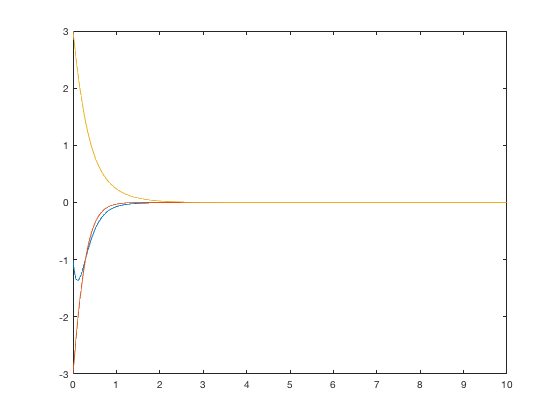

sys = @(t,x)sistema_lineal(t,x,K,Ac,B);
[t,x] = ode45(sys,[0,tf],x0); %opciones);
figure(3)
plot(t,x)

u = K*x'

u =   -16.0135  -15.7504  -15.4858  -15.2204  -14.9543  -13.9345  -12.9282  -11.9476  -11.0033  -10.0774   -9.2015   -8.3780   -7.6088   -6.8024   -6.0642   -5.3915   -4.7815   -4.1743   -3.6341   -3.1552   -2.7325   -2.3253   -1.9730   -1.6688   -1.4073   -1.1612   -0.9543   -0.7810   -0.6362   -0.5017   -0.3928   -0.3050   -0.2346   -0.1694   -0.1197   -0.0821   -0.0539   -0.0352   -0.0208   -0.0100   -0.0019    0.0037    0.0078    0.0107    0.0128    0.0140    0.0148    0.0151    0.0151    0.0149
    8.7582    8.2808    7.8252    7.3905    6.9759    5.5542    4.3725    3.3942    2.5867    1.9046    1.3502    0.9027    0.5437    0.2238   -0.0196   -0.2010   -0.3334   -0.4361   -0.5017   -0.5388   -0.5548   -0.5554   -0.5426   -0.5205   -0.4928   -0.4589   -0.4233   -0.3873   -0.3524   -0.3154   -0.2812   -0.2498   -0.2215   -0.1922   -0.1667   -0.1445   -0.1254   -0.1110   -0.0983   -0.0873   -0.0776   -0.0697   -0.0626   -0.0564   -0.0509   -0.0461   -0.0418   -0.0380   -0.0346   -0

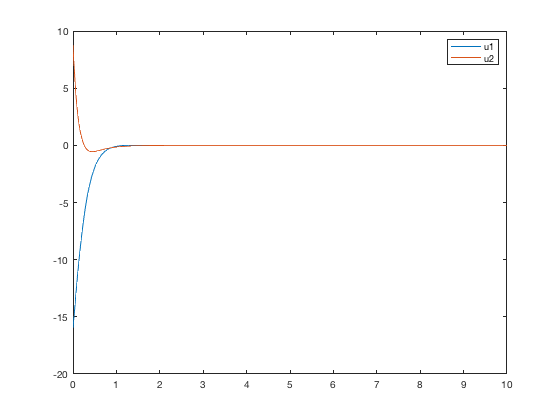

figure(4)
plot(t,u)
legend('u1','u2')

 Es interesante fijarse en que la primera entrada está fuera del límite impuesto. La razón es que el criterio de Bryson marca un límite mínimo. Si queremos conseguir que ambas entradas cumplan el criterio debemos forzar más la condición una forma de hacerlo es aumentar los pesos de la matriz $\bar{R}$ probar por ejemplo con un valor $\bar{a}_{ii} = 0.1 $ (haz tú la prueba).  NOTA, todo esto es un ejercio de tanteo, si pruebas con otros valores puedes ver la sensibilidad de la respuesta y la entrada a los valores de $\bar{Q} \ \text{y}\  \bar{R}$

Supongamos ahora que solo quiere imponer concidiciones sobre los dos primeros estados, pero no sobre el tercero. Entonces podría modificar mi $z$  $\bar{Q}$ y $H$

$z=\pmatrix{1&0&0\cr 0&1&0}x$ etc.

G = [1 0 0;0 0 1] %ojo est G no el la que se decribe en el texto, aquí estamos empleando los estados x1 y x3 

G =      1     0     0
     0     0     1


Qbar = [1/2^2 0;0 1/2^2]  %aplico el criterio de Bryson pero ahora no quiero que los estados 1 y 3 superen el valor 2

Qbar =     0.2500         0
         0    0.2500


H =zeros(2,2)

H =      0     0
     0     0


Q = G'*Qbar*G

Q =     0.2500         0         0
         0         0         0
         0         0    0.2500


R = H'*Qbar*H+rho*Rbar

R =     0.0100         0
         0    0.0100


N = G'*Qbar*H

N =      0     0
     0     0
     0     0


rho = 0.0001 %vuelvo a relajar las condiciones sobre la entrada. No he cambido Rbar, por lo que conservo el valor del ejemplo anterior

rho = 1.0000e-04

[K,P,la]= lqr(Ac,B,Q,R,N)

K =     1.4350    4.5518    0.6824
    5.9857   -3.1157    0.6703


P =     0.0299   -0.0156    0.0034
   -0.0156    0.0611    0.0035
    0.0034    0.0035    0.0602


la =    -2.1992
   -2.9103
  -10.8487



sys = @(t,x)sistema_lineal(t,x,K,Ac,B);
x0 = [2 -2 2]

x0 =      2    -2     2


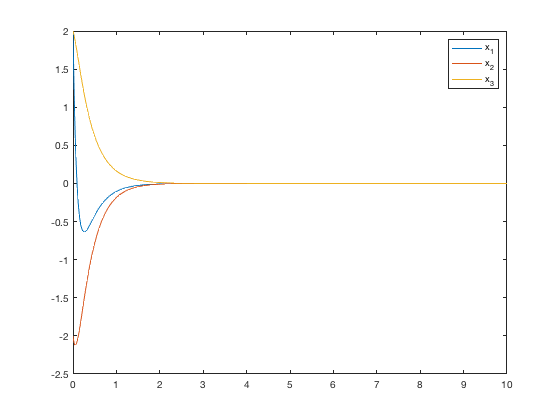

[t,x] = ode45(sys,[0,tf],x0); %opciones);
figure(5)
plot(t,x)
legend('x_1','x_2','x_3')

u = K*x'

u =    -4.8688   -5.0770   -5.2761   -5.4666   -5.6485   -6.4414   -7.0606   -7.5323   -7.8802   -8.1522   -8.3124   -8.3809   -8.3760   -8.3275   -8.2455   -8.1360   -8.0041   -7.8120   -7.5983   -7.3687   -7.1287   -6.8476   -6.5626   -6.2773   -5.9948   -5.6775   -5.3689   -5.0707   -4.7842   -4.4682   -4.1692   -3.8871   -3.6218   -3.3352   -3.0696   -2.8238   -2.5967   -2.3528   -2.1311   -1.9297   -1.7471   -1.5505   -1.3758   -1.2206   -1.0828   -0.9324   -0.8029   -0.6912   -0.5951   -0.4835
   19.5434   18.9909   18.4545   17.9338   17.4283   15.1130   13.1164   11.3949    9.9093    8.4565    7.2282    6.1900    5.3109    4.6866    4.1419    3.6665    3.2511    2.7985    2.4164    2.0936    1.8202    1.5580    1.3402    1.1590    1.0077    0.8633    0.7448    0.6474    0.5666    0.4889    0.4255    0.3734    0.3300    0.2877    0.2527    0.2236    0.1990    0.1740    0.1530    0.1352    0.1199    0.1037    0.0900    0.0784    0.0683    0.0573    0.0482    0.0406    0.0342    0

Controlo $x_1$ y $x_3$

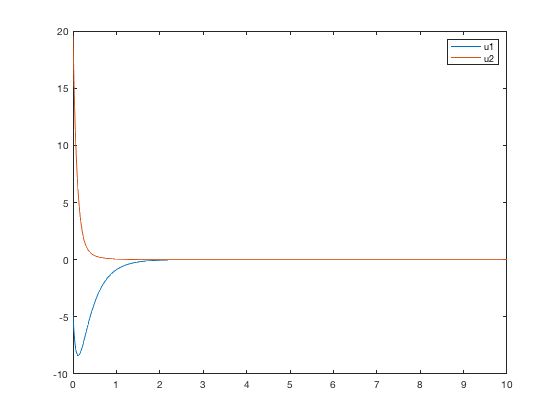

figure(6)
plot(t,u)
legend('u1','u2')

Si nos fijamos en los estados $x_1$ y $x_3$ cumplen la restricción impuesta, El valor de $x_2$ ahora no está sometido a restricción y toma el valor máximo que quiere. Ahora las entradas ya no están acotadas como antes debido al pequeño valor de $\rho$

function xdot = sistema_lineal(t,x,K,A,B)
%modificamos el sistema lineal para ponerlo en modo realimentación
u = -K*x;
xdot = A*x+B*u;
end